# Classify Text Data Using Multiscale Convolutional Neural Network

This example shows how to classify text data using a convolutional neural network.

To classify text data using convolutions, use 1-D convolutional layers that convolve over the time dimension of the input.

This example trains a network with 1-D convolutional filters of varying widths. The width of each filter corresponds the number of words the filter can see (the n-gram length). The network has multiple branches of convolutional layers, so it can use different n-gram lengths.

## Load Data

Create a tabular text datastore from the data in `factoryReports.csv` and view the first few reports.

load('textdataset.mat')

Partition the data into training and validation partitions. Use 80% of the data for training and the remaining data for validation.

## Preprocess Text Data

Extract the text data from the `"Description"` column of the table and preprocess it using the `preprocessText` function, listed in the section Preprocess Text Function of the example.

documentsTrain = preprocessText(dataTrain.Description);

Extract the labels from the `"Category"` column and convert them to categorical.

TTrain = categorical(dataTrain.Category);

View the class names and the number of observations.

classNames = unique(TTrain)

classNames = 5×1 categorical 数组
     General early blight 
     General late blight 
     Severe early blight 
     Severe late blight 
     health 


numObservations = numel(TTrain)

numObservations = 1528

Extract and preprocess the validation data using the same steps.

documentsValidation = preprocessText(dataValidation.Description);
TValidation = categorical(dataValidation.Category);

## Convert Documents to Sequences

To input the documents into a neural network, use a word encoding to convert the documents into sequences of numeric indices.

Create a word encoding from the documents.

enc = wordEncoding(documentsTrain);

View the vocabulary size of the word encoding. The vocabulary size is the number of unique words of the word encoding.

numWords = enc.NumWords

numWords = 395

Convert the documents to sequences of integers using the `doc2sequence` function.

XTrain = doc2sequence(enc,documentsTrain);

Convert the validation documents to sequences using the word encoding created from the training data.

XValidation = doc2sequence(enc,documentsValidation);

## Define Network Architecture

Define the network architecture for the classification task.

The following steps describe the network architecture.

- Specify an input size of 1, which corresponds to the channel dimension of the integer sequence input.

- Embed the input using a word embedding of dimension 100.

- For the n-gram lengths 2, 3, 4, and 5, create blocks of layers containing a convolutional layer, a batch normalization layer, a ReLU layer, a dropout layer, and a max pooling layer.

- For each block, specify 200 convolutional filters of size 1-by-*N* and a global max pooling layer.

- Connect the input layer to each block and concatenate the outputs of the blocks using a concatenation layer.

- To classify the outputs, include a fully connected layer with output size *K*, and a softmax layer, where *K* is the number of classes.

Specify the network hyperparameters.

embeddingDimension = 100;
ngramLengths = [2 3 4 5];
numFilters = 200;

First, create a `dlnetwork` object containing the input layer and a word embedding layer of dimension 100. To help connect the word embedding layer to the convolution layers, set the word embedding layer name to `"emb"`. To check that the convolution layers do not convolve the sequences to have a length of zero during training, set the `MinLength` option to the length of the shortest sequence in the training data.

net = dlnetwork;
minLength = min(doclength(documentsTrain));
layers = [ 
    sequenceInputLayer(1,MinLength=minLength)
    wordEmbeddingLayer(embeddingDimension,numWords,Name="emb")];
net = addLayers(net,layers);

For each of the n-gram lengths, create a block of 1-D convolution, batch normalization, ReLU, dropout, and 1-D global max pooling layers. Connect each block to the word embedding layer.

numBlocks = numel(ngramLengths);
for j = 1:numBlocks
    N = ngramLengths(j);
    
    block = [
        convolution1dLayer(N,numFilters,Name="conv"+N,Padding="same")
        batchNormalizationLayer(Name="bn"+N)
        reluLayer(Name="relu"+N)
        dropoutLayer(0.2,Name="drop"+N)
        globalMaxPooling1dLayer(Name="max"+N)];
    
    net = addLayers(net,block);
    net = connectLayers(net,"emb","conv"+N);
end

Add the concatenation layer, the fully connected layer, and the softmax layer. 

numClasses = numel(classNames);

layers = [
    concatenationLayer(1,numBlocks,Name="cat")
    fullyConnectedLayer(numClasses,Name="fc")
    softmaxLayer(Name="soft")];

net = addLayers(net,layers);

Connect the global max pooling layers to the concatenation layer and view the network architecture in a plot.

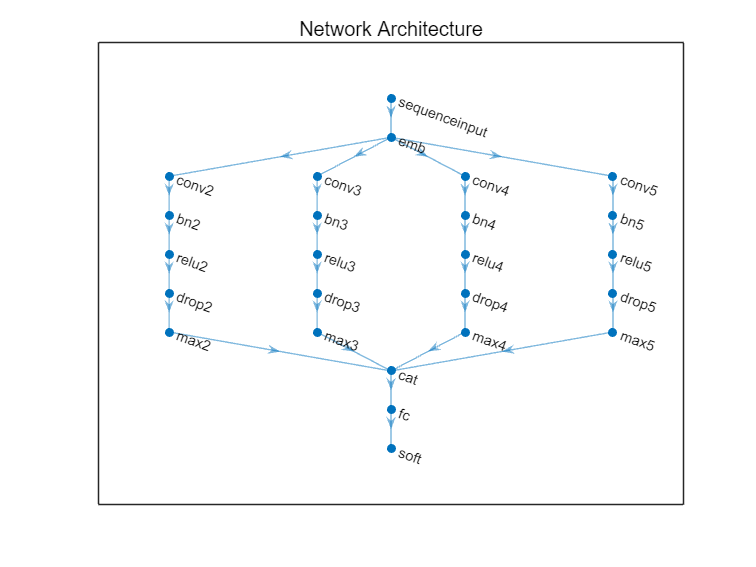

for j = 1:numBlocks
    N = ngramLengths(j);
    net = connectLayers(net,"max"+N,"cat/in"+j);
end

figure
plot(net)
title("Network Architecture")

## Train Network

Specify the training options:

- Train with a mini-batch size of 128. By default, the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function uses a GPU if one is available. Training on a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the `trainnet` function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

- Validate the network using the validation data. 

- Return the network with the lowest validation loss.

- Monitor the training progress in a plot and monitor the accuracy metric.

- Suppress the verbose output.

- Because the training data has sequences with rows and columns corresponding to channels and time steps, respectively, specify the input data format `"CTB"`  (channel, time, batch).

options = trainingOptions("adam", ...
    MiniBatchSize=128, ...
    ValidationData={XValidation,TValidation}, ...
    OutputNetwork="best-validation", ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false, ...
    InputDataFormats='CTB');

Train the network using the `trainnet` function.

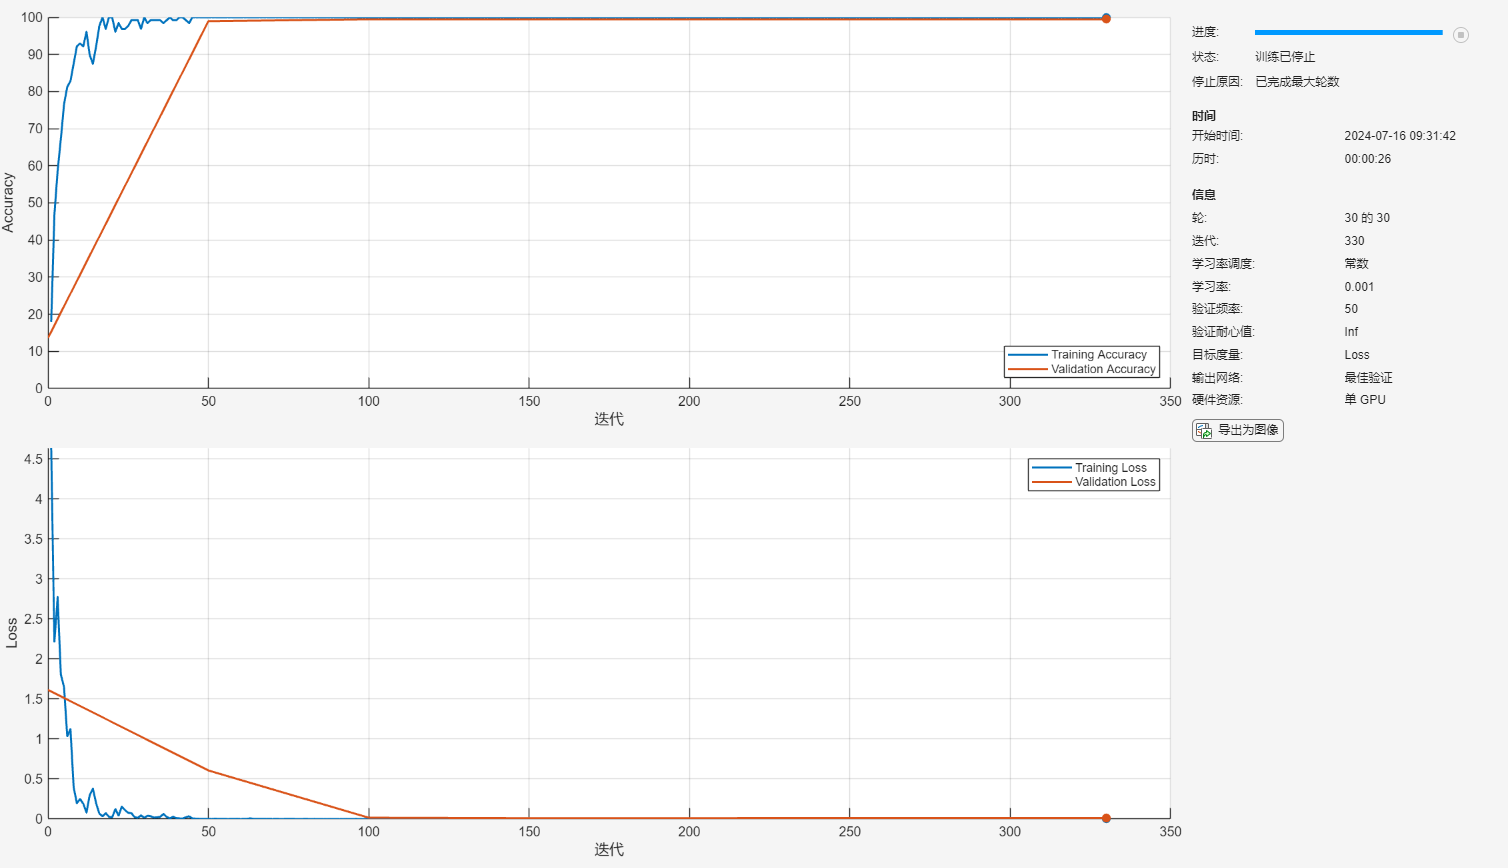

net = trainnet(XTrain,TTrain,net,"crossentropy",options);

## Test Network

Make predictions using the neural network. To make predictions with multiple observations, use the `minibatchpredict` function. To convert the prediction scores to labels, use the `scores2label` function. The `minibatchpredict` function automatically uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the function uses the CPU.

Because the data has sequences with rows and columns corresponding to channels and time steps, respectively, specify the input data format `"CTB"`  (channel, time, batch).

scores = minibatchpredict(net,XValidation,InputDataFormats="CTB");
YValidation = scores2label(scores,classNames);

Visualize the predictions in a confusion chart.

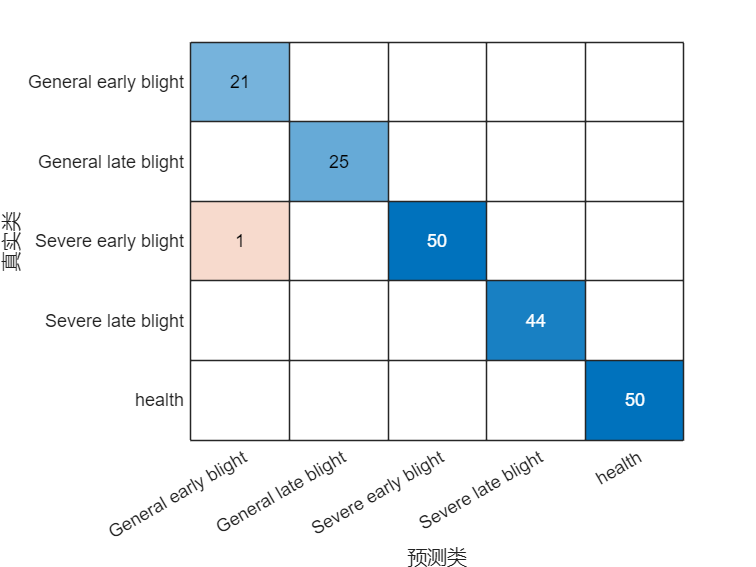

figure
confusionchart(TValidation,YValidation)

Calculate the classification accuracy. The accuracy is the proportion of labels predicted correctly.

Valaccuracy = mean(TValidation == YValidation)

Valaccuracy = 0.9948

## Predict Using New Data

Classify the event type of three new reports. Create a string array containing the new reports.

documentsTest = preprocessText(dataTest.Description);
TTest = categorical(dataTest.Category);
XTest = doc2sequence(enc,documentsTest);

Classify the test sequences using the trained network.

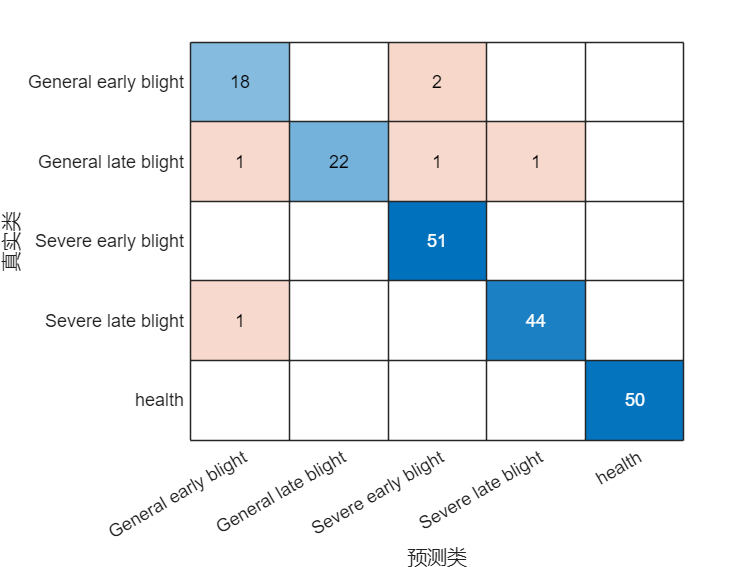

scores1 = minibatchpredict(net,XTest,InputDataFormats="CTB");
YTest= scores2label(scores1,classNames);
figure
confusionchart(TTest,YTest)

Testaccuracy = mean(TTest == YTest)

Testaccuracy = 0.9686

## Preprocess Text Function

The `preprocessTextData` function takes text data as input and performs these steps:

- Tokenize the text.

- Convert the text to lowercase.

function documents = preprocessText(textData)

documents = tokenizedDocument(textData);
documents = lower(documents);

end